Get operating point

% run trimming.m file
run('linear_analysis/trimming.m')

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(5.92476e-01) main_to_linearize/Drone Dynamics/Actuator Dynamics/motor_thrus_resp_bot
(3.24486e-11) main_to_linearize/Drone Dynamics/Actuator Dynamics/motor_thrus_resp_bot
(3.24486e-11) 

Linearize model from rate input to rate output

mdl = 'main_to_linearize'

mdl = 'main_to_linearize'

io(1) = linio('main_to_linearize/att_control/pitch_rate', 1, 'openinput')


1x2 vector of Linearization IOs: 
--------------------------
1. Linearization open-loop input located at the following signal:
- Block: main_to_linearize/att_control/pitch_rate
- Port: 1
2. Linearization open-loop output located at the following signal:
- Block: main_to_linearize/Drone Dynamics/w_b_comp
- Port: 2
- Signal Name: w_y


io(2) = linio('main_to_linearize/Drone Dynamics/w_b_comp', 2, 'openoutput')


1x2 vector of Linearization IOs: 
--------------------------
1. Linearization open-loop input located at the following signal:
- Block: main_to_linearize/att_control/pitch_rate
- Port: 1
2. Linearization open-loop output located at the following signal:
- Block: main_to_linearize/Drone Dynamics/w_b_comp
- Port: 2
- Signal Name: w_y



G_rate = linearize(mdl, io, op)


G_rate =
 
  A = 
                    p,q,r (1)     p,q,r (2)  bx_actuator_  bx_actuator_  by_actuator_  by_actuator_  Transport De  Transport De
   p,q,r (1)                0      7.74e-34         129.1    -1.055e+04             0             0          5911             0
   p,q,r (2)        -7.74e-34             0             0             0         129.1    -1.055e+04             0          5911
   bx_actuator_             0             0        -13.13        -72.64             0             0             0             0
   bx_actuator_             0             0             1             0             0             0             0             0
   by_actuator_             0             0             0             0        -13.13        -72.64             0             0
   by_actuator_             0             0             0             0             1             0             0             0
   Transport De             0             0       -0.8738         71.42             0

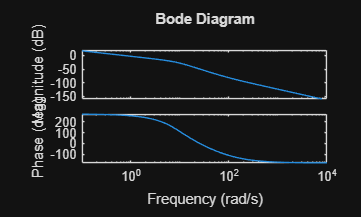

bode(G_rate)

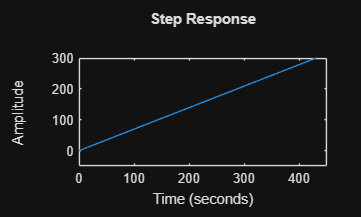

step(G_rate)

[num, den] = ss2tf(G_rate.A, G_rate.B, G_rate.C, G_rate.D)

num = 1.0e+06 *

         0         0    0.0000   -0.0000   -0.0009    0.0133    0.2482    1.4726    0.0000


den = 1.0e+06 *

    0.0000    0.0001    0.0018    0.0251    0.2087    0.9743    2.1109         0         0


s = tf('s')


s =
 
  s
 
Continuous-time transfer function.


G_rate_tf = tf(num, den) * exp(-0.2*s)


G_rate_tf =
 
                0.62 s^6 - 42.53 s^5 - 868.5 s^4 + 1.333e04 s^3 + 2.482e05 s^2 + 1.473e06 s + 4.845e-07
  exp(-0.2*s) * ---------------------------------------------------------------------------------------
                s^8 + 66.27 s^7 + 1768 s^6 + 2.512e04 s^5 + 2.087e05 s^4 + 9.743e05 s^3 + 2.111e06 s^2
 
Continuous-time transfer function.


[A,B,C,D] = tf2ss(G_rate_tf.Numerator{1}, G_rate_tf.Denominator{1})

A = 1.0e+06 *

   -0.0001   -0.0018   -0.0251   -0.2087   -0.9743   -2.1109         0         0
    0.0000         0         0         0         0         0         0         0
         0    0.0000         0         0         0         0         0         0
         0         0    0.0000         0         0         0         0         0
         0         0         0    0.0000         0         0         0         0
         0         0         0         0    0.0000         0         0         0
         0         0         0         0         0    0.0000         0         0
         0         0         0         0         0         0    0.0000         0


B =      1
     0
     0
     0
     0
     0
     0
     0


C = 1.0e+06 *

         0    0.0000   -0.0000   -0.0009    0.0133    0.2482    1.4726    0.0000


D = 0

G_rate = ss(A,B,C,D)


G_rate =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8
   x1      -66.27       -1768  -2.512e+04  -2.087e+05  -9.743e+05  -2.111e+06           0           0
   x2           1           0           0           0           0           0           0           0
   x3           0           1           0           0           0           0           0           0
   x4           0           0           1           0           0           0           0           0
   x5           0           0           0           1           0           0           0           0
   x6           0           0           0           0           1           0           0           0
   x7           0           0           0           0           0           1           0           0
   x8           0           0           0           0           0           0           1           0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
   x

Control System Designer

step(G_rate)